% Initializing script
clc, clf, clear

constants;

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i)/P_c_ref, 1, 1]);
    total_mass_A_t(i) = calc_objective([1, A_t(i)/A_t_ref, 1]);
    total_mass_A_e(i) = calc_objective([1, 1, A_e(i)/A_e_ref]);
end

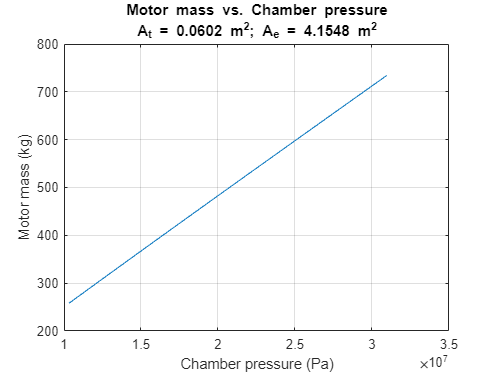

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

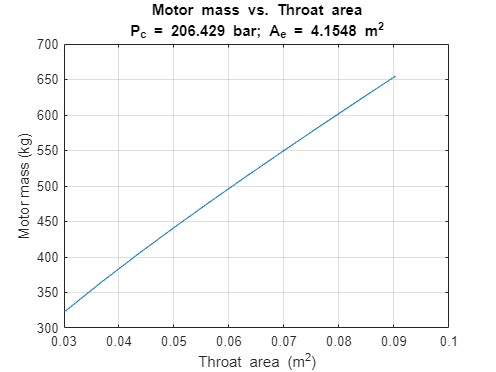


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

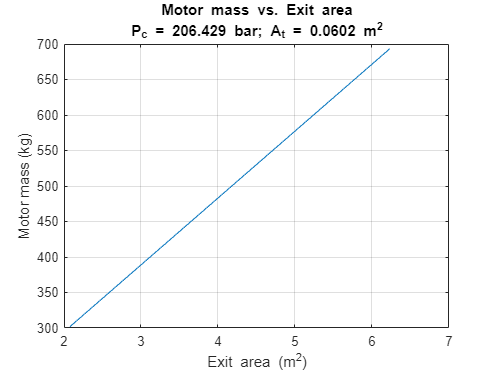


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            x_scaled = scale([P_c(i), A_t(j), A_e(k)], x_ref);
            total_mass_val(i, j, k) = calc_objective(x_scaled);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints(x_scaled);
        end
    end
end

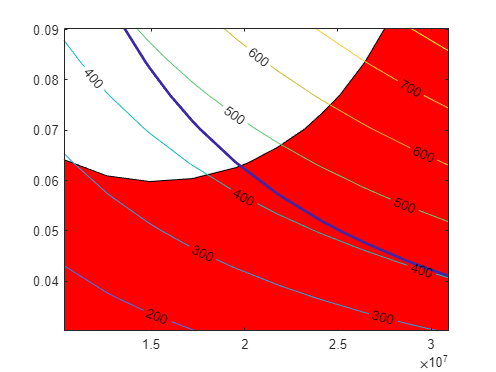

% Example plot
clf
i = 4;
contourf(P_c, A_t, ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(P_c, A_t, eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(P_c, A_t, total_mass_val(:,:, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [0.5, 0.5, 0.2];
ub = [1.5, 1.5, 1.5];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
x0 = [0.7, 0.75, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    2.936433e+02     4.864e-01     1.000e+00     0.000e+00     4.023e+02  
    1           8    1.841255e+02     1.363e-01     1.000e+00     1.099e+00     4.662e+02  
    2          12    2.764250e+02     3.984e-02     1.000e+00     2.598e-01     2.211e+02  
    3          18    2.502606e+02     1.052e-01     7.000e-01     8.400e-01     6.185e+01  
    4          22    2.646984e+02     6.355e-02     1.000e+00     4.081e-01     3.319e+02  
    5          26    2.905994e+02     5.616e-06     1.000e+00     5.041e-02     4.497e+01  
    6          30    2.906309e+02     8.617e-10     1.000e+00     6.807e-05     3.934e-02  
    7          34    2.906309e+02     2.220e-16     1.000e+00     1.041e-08     1.143e-04  



x =     1.5000    0.6668    0.4167


fval = 290.6309

exitflag = 1

output = struct with fields:
         iterations: 7
          funcCount: 34
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.383023e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 2.220446e-16, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 2.2204e-16
           stepsize: 1.0412e-08
       lssteplength: 1
      firstorderopt: 1.1428e-04
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: 406.8423
       ineqlin: [0×1 double]
    ineqnonlin: 5.5922e+03
         lower: [3×1 double]
         upper: [3×1 double]


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 30964350.000000
Throat area = 0.040143
Exit area = 1.731310
Total Mass = 290.630864

ans = 0.8310